# Maximum Likelihood Estimation

clear; clc; 
cd('/Users/duncan/Documents/GitHub/Advanced-Biomedical-Experimental-Design-and-Statistics/Maximum LIkelihood Estimation')

## Binomial Distribution

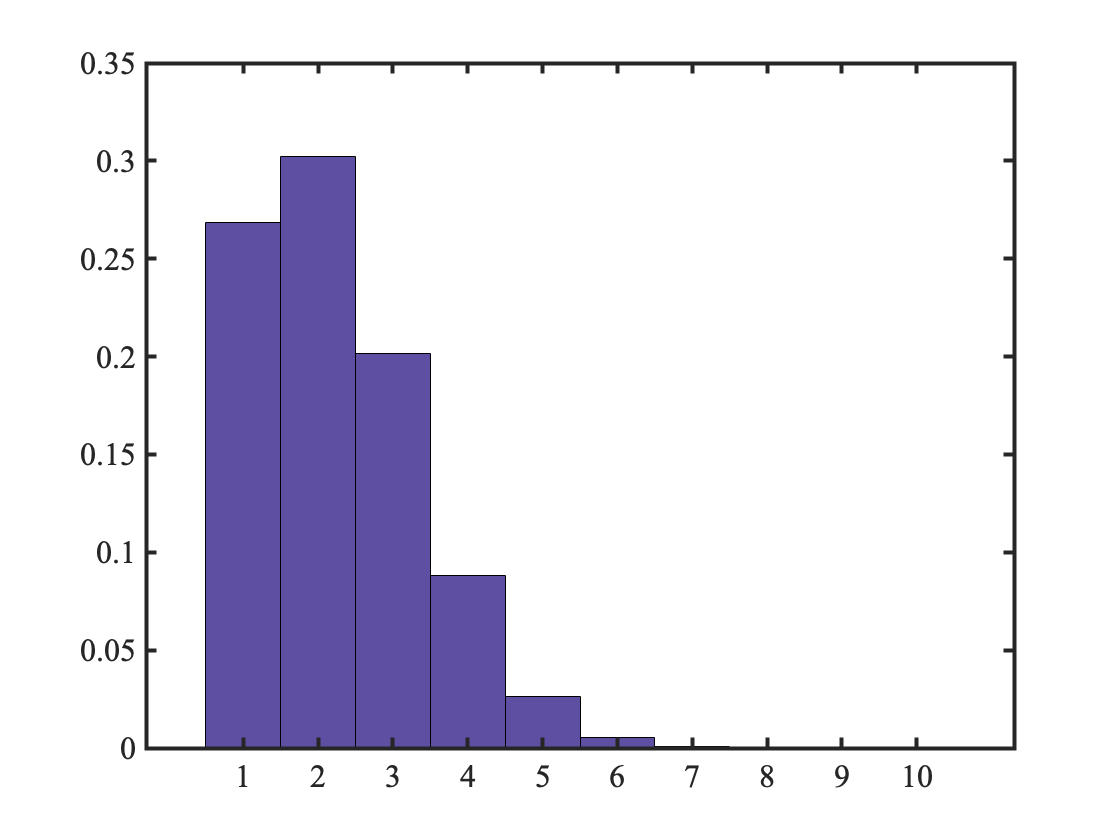

x = 1:10;
I = 10;
w = 0.2; 
y = binopdf(x, I, w);

figure();
bar(x,y,1)

## Binomial Distribution - Varying a Parameter

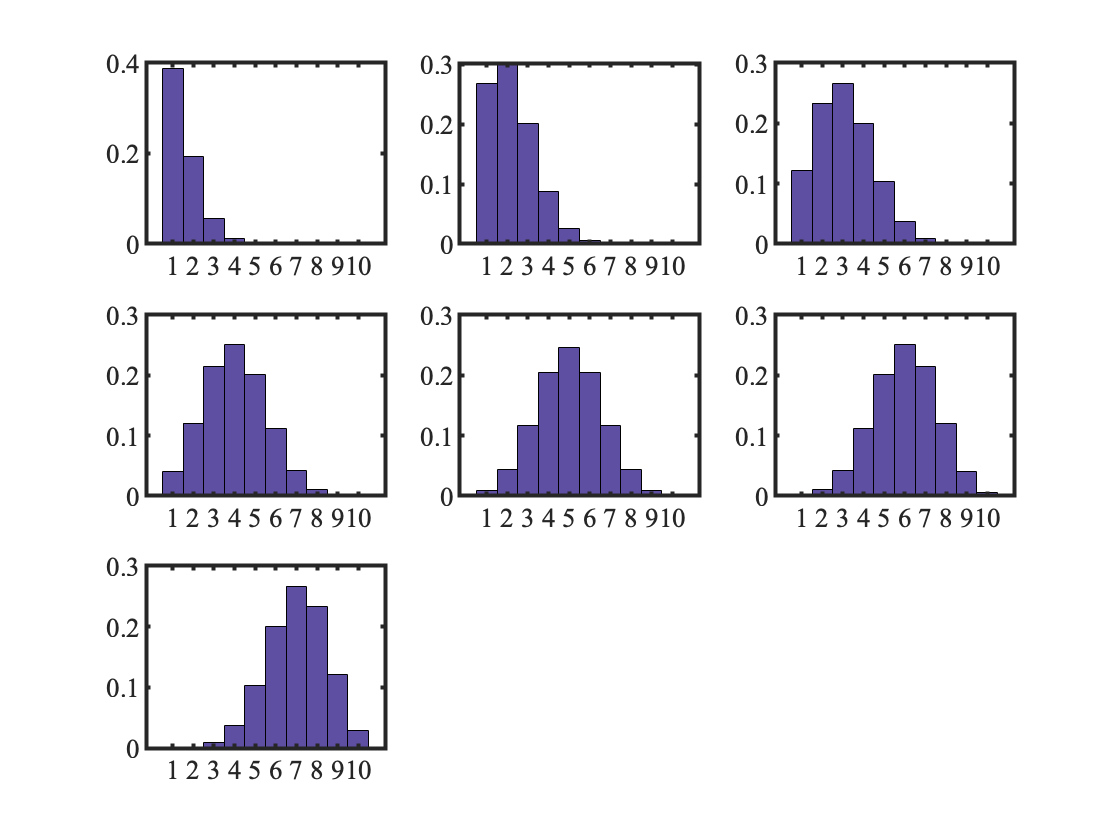

w_s = 0.1:0.1:0.7;

figure(); 
for i = 1:length(w_s)
    y = binopdf(x, I, w_s(i));
    
    subplot(3,3,i)
    bar(x,y,1)
    
end

## Graphing the Likelihood Function

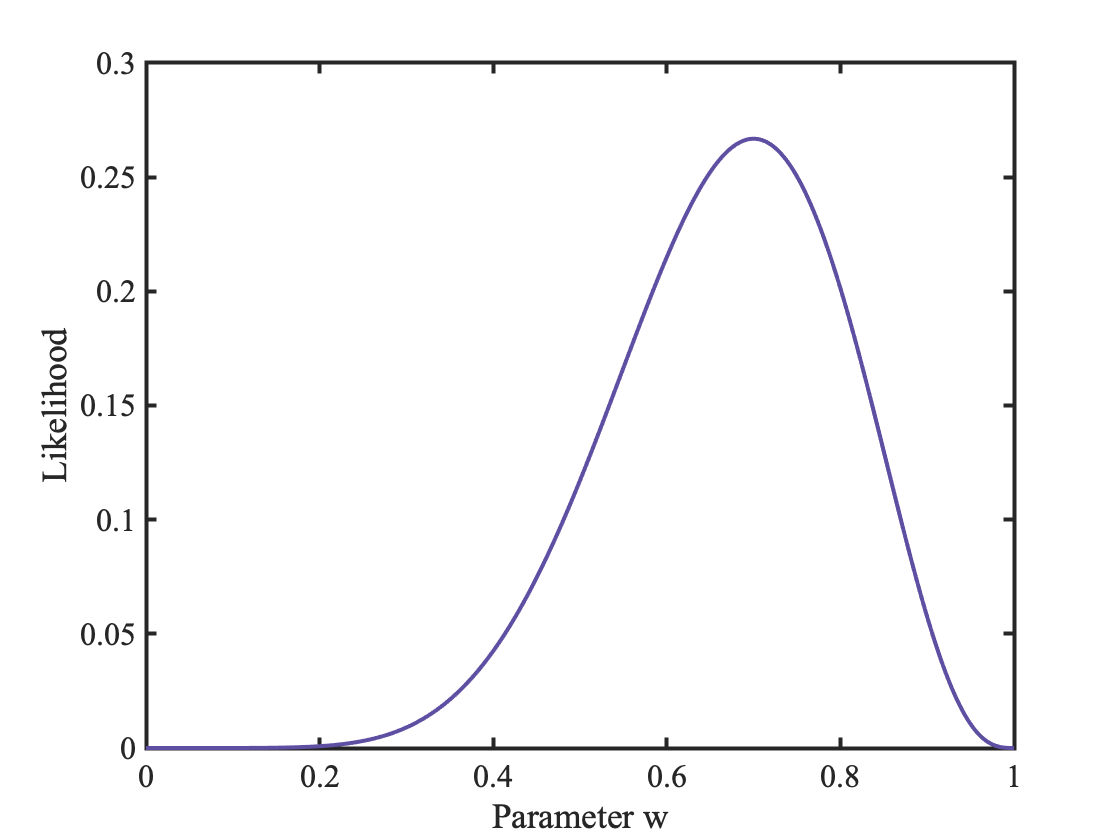

w = linspace(0,1,1e3);
binoLikelihood = @(n,y,w) (factorial(n) / (factorial(y) * factorial(n-y))) * w^y * (1 - w)^(n-y);
like = nan(size(w)); 
for i = 1:length(w)
    like(i) = binoLikelihood(I,7,w(i));
end

figure();
plot(w, like);
xlabel('Parameter w')
ylabel('Likelihood')

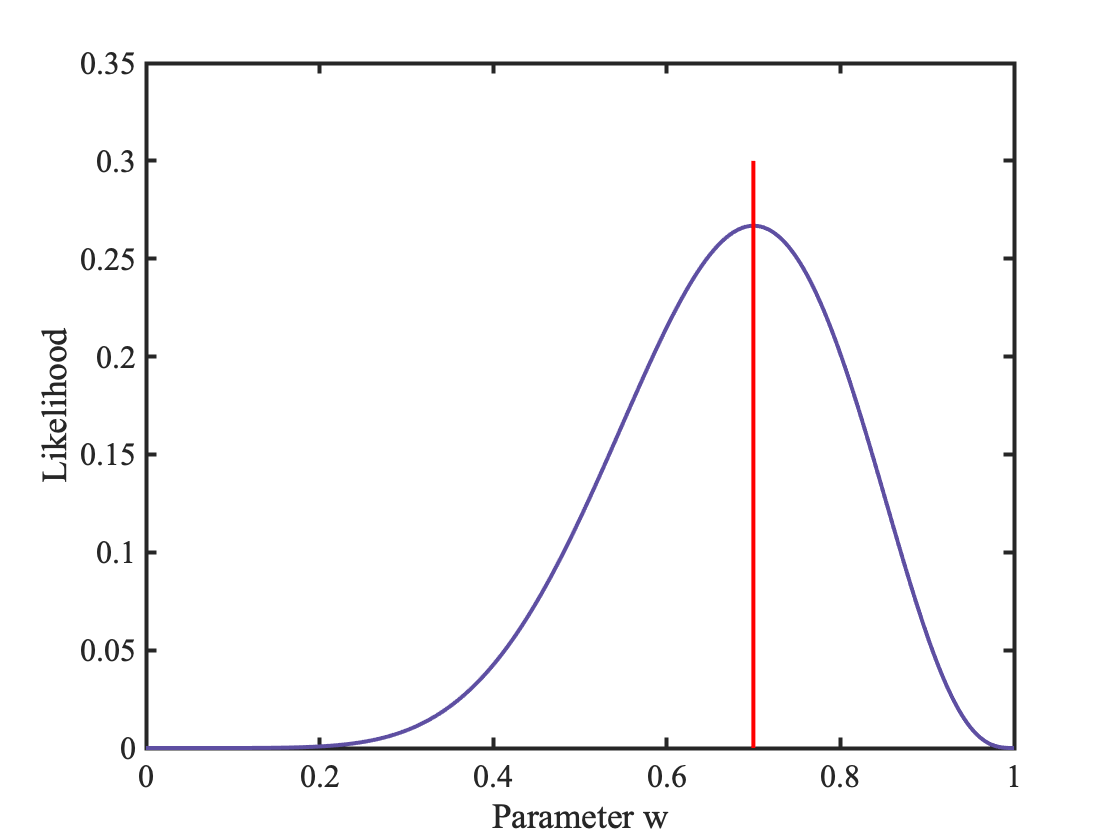


figure();
plot(w, like);
hold on 
[maxLike, maxLikeIdx] = max(like);
plot([w(maxLikeIdx) w(maxLikeIdx)], get(gca,'ylim'), 'r-')
xlabel('Parameter w')
ylabel('Likelihood')

## MLE - BRUTE FORCE

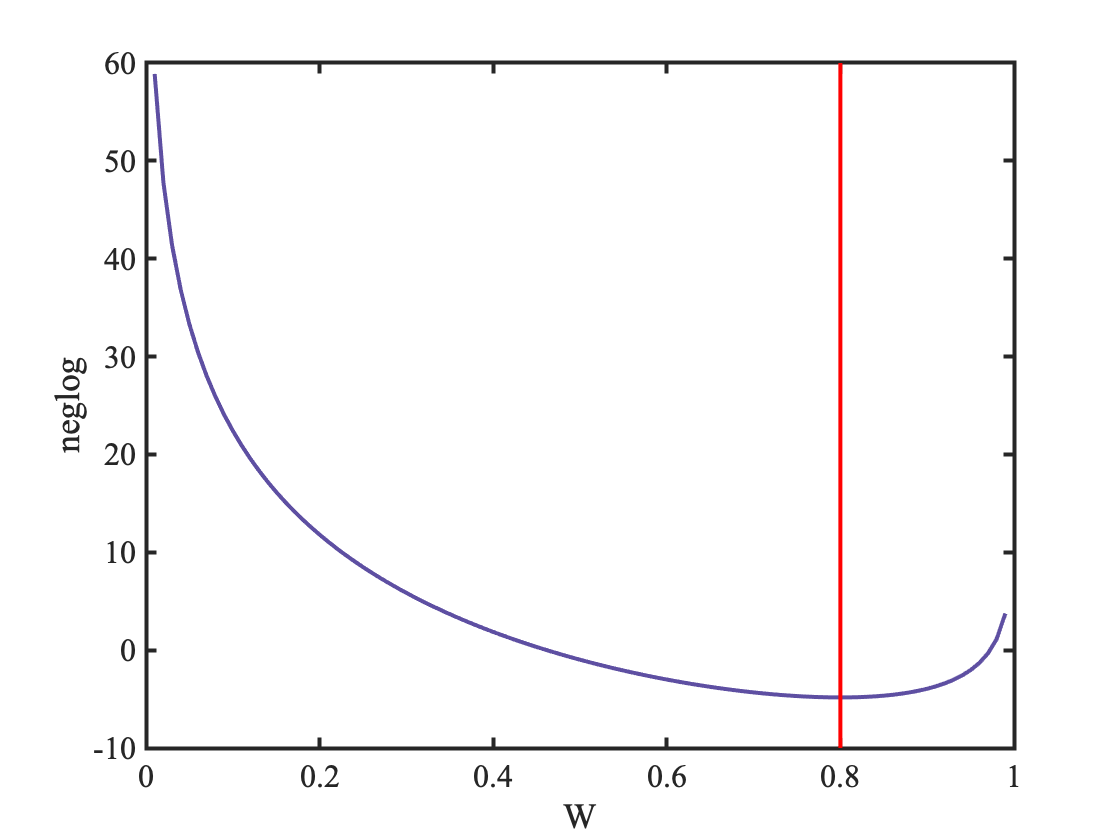

I = 100;
neglog = nan(I,1);
W = nan(I,1);
n = 20;
y = 16; 
for i = 1:I
    w = i * 0.01;
    neglog(i) = -((log(factorial(n)/factorial(y)*factorial(n-y)))+y*log(w)+(n-y)*log(1-w));
    W(i) = w; 
end

figure();
plot(W, neglog);
hold on;
[maxNLL, maxNLLIdx] = min(neglog);
plot([W(maxNLLIdx) W(maxNLLIdx)], get(gca,'ylim'), 'r-');
xlabel('W');
ylabel('neglog')

## MLE - OPTIMIZER

nll = @(n, y, w) -((log(factorial(n)/factorial(y)*factorial(n-y)))+y*log(w)+(n-y)*log(1-w));
fminsearch(@(x) nll(n, y, x), 0.5)

ans = 0.8000

## Likelihood Ratio Test

1 - chi2cdf(11.46982, 1)

ans = 7.0736e-04